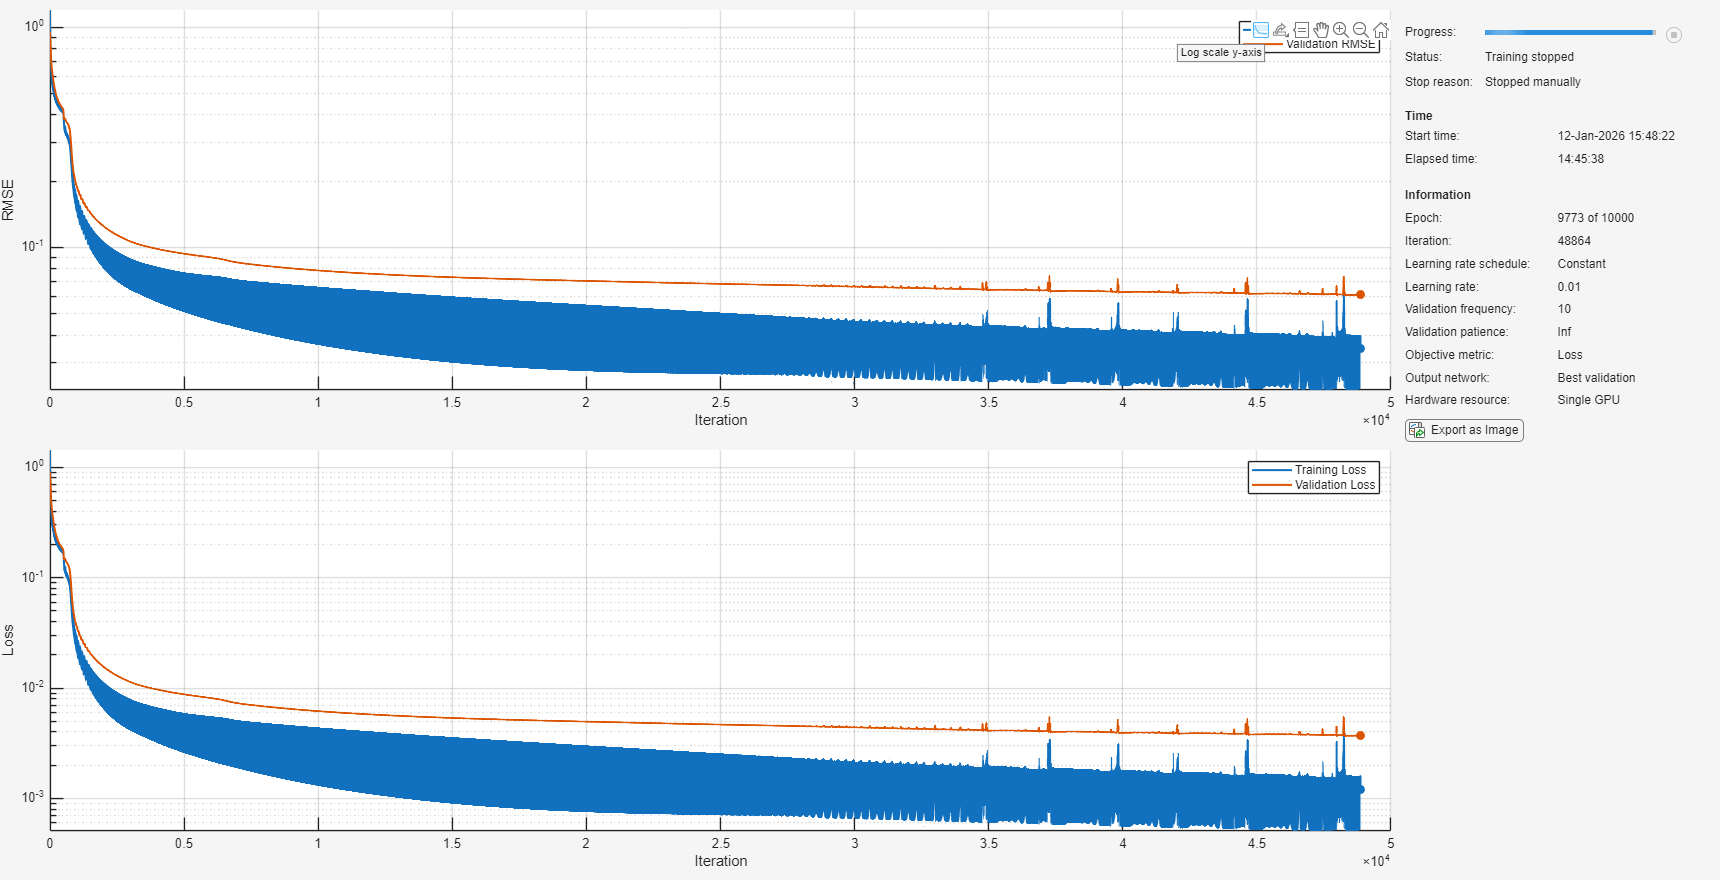

%% 2-Link Arm Reaching Task with LQR Controller, Neural Network Training, and Comparison
% (2) joint-space error inputs with periodic encoding
% (4) z-score normalisation (angles via sin/cos)
% (5) episode-level train/val split (no leakage)
% (9) identical horizons for LQR vs NN

clear; clc; close all;
rng(1)

%% System Setup
A = [0 0 1 0;
     0 0 0 1;
     0 0 0 0;
     0 0 0 0];
B = [0 0;
     0 0;
     1 0;
     0 1];

Q = diag([100, 100, 1, 1]);
R = diag([0.1, 0.1]);
K = lqr(A, B, Q, R);

dt = 0.01;
T  = 5;
t  = 0:dt:T;

l1 = 1.0;
l2 = 0.8;

%% Data Generation
numEpisodes = 250;
sampleInterval = 1;

inputsEpisodes  = cell(numEpisodes,1);  % each: 6xNi
outputsEpisodes = cell(numEpisodes,1);  % each: 2xNi

for ep = 1:numEpisodes
    r = 0.5 + (l1+l2 - 0.5)*rand;
    angle = 2*pi*rand;
    x_target_ee = r*cos(angle);
    y_target_ee = r*sin(angle);
    
    c2 = (x_target_ee^2 + y_target_ee^2 - l1^2 - l2^2) / (2*l1*l2);
    c2 = max(min(c2,1),-1);
    theta2_des = acos(c2);
    k1 = l1 + l2*cos(theta2_des);
    k2 = l2*sin(theta2_des);
    theta1_des = atan2(y_target_ee, x_target_ee) - atan2(k2, k1);
    x_target_joint = [theta1_des; theta2_des; 0; 0];
    
    x_sim = zeros(4, length(t));
    x_sim(:,1) = [0; 0; 0; 0];
    
    epiInputs  = [];
    epiOutputs = [];
    consecutiveCounter = 0;
    
    for k = 1:length(t)-1
        e_joint = x_sim(:,k) - x_target_joint;
        u = -K * e_joint;
        
        x_sim(:,k+1) = x_sim(:,k) + dt*(A*x_sim(:,k) + B*u);
        
        if mod(k, sampleInterval) == 0
            theta1_err = e_joint(1);
            theta2_err = e_joint(2);
            phi = [sin(theta1_err); cos(theta1_err); ...
                   sin(theta2_err); cos(theta2_err); ...
                   e_joint(3); e_joint(4)];          % 6 features
            epiInputs  = [epiInputs,  phi];
            epiOutputs = [epiOutputs, u];
        end
        
        % early stop for data-gen
        th1 = x_sim(1,k+1);
        th2 = x_sim(2,k+1);
        x1_sim = l1 * cos(th1);
        y1_sim = l1 * sin(th1);
        x_end_sim = x1_sim + l2 * cos(th1+th2);
        y_end_sim = y1_sim + l2 * sin(th1+th2);
        dist_sim = hypot(x_end_sim - x_target_ee, y_end_sim - y_target_ee);
        if dist_sim < 0.01
            consecutiveCounter = consecutiveCounter + 1;
        else
            consecutiveCounter = 0;
        end
        if consecutiveCounter >= 10
            break;
        end
    end
    
    inputsEpisodes{ep}  = epiInputs;
    outputsEpisodes{ep} = epiOutputs;
end

%% Episode-level split (fix: use numeric indices + robust concat)
idxEp = randperm(numEpisodes);
numTrainEp = round(0.8 * numEpisodes);
trainEps = idxEp(1:numTrainEp);
valEps   = idxEp(numTrainEp+1:end);

concatCells = @(C, idx) localConcat(C, idx);  % robust concatenation

XTrainAll = concatCells(inputsEpisodes,  trainEps);
YTrainAll = concatCells(outputsEpisodes, trainEps);
XValAll   = concatCells(inputsEpisodes,  valEps);
YValAll   = concatCells(outputsEpisodes, valEps);

if isempty(XTrainAll), error('No training samples aggregated.'); end
if isempty(XValAll),   error('No validation samples aggregated.'); end

%% Normalisation (training stats only)
mu_X = mean(XTrainAll, 2);
sigma_X = std(XTrainAll, 0, 2);  sigma_X(sigma_X==0) = 1;

mu_Y = mean(YTrainAll, 2);
sigma_Y = std(YTrainAll, 0, 2);  sigma_Y(sigma_Y==0) = 1;

numInputs = size(XTrainAll,1);   % expect 6

XTrain = ((XTrainAll - mu_X) ./ (sigma_X*sqrt(numInputs)))';   % [N x 6]
YTrain = ((YTrainAll - mu_Y) ./ sigma_Y)';   % [N x 2]
XVal   = ((XValAll   - mu_X) ./ (sigma_X*sqrt(numInputs)))'; 
YVal   = ((YValAll   - mu_Y) ./ sigma_Y)';



%% Network (kept structure per your code)
layers = [
    featureInputLayer(numInputs,'Normalization','none','Name','input')
    fullyConnectedLayer(16e3,'Name','fc1','WeightsInitializer',@customWeights1_git,'WeightLearnRateFactor',0,'BiasInitializer','zeros')
    tanhLayer('Name','relu1')
    fullyConnectedLayer(16e3,'Name','fc2','WeightsInitializer',@customWeights2_git,'WeightLearnRateFactor',0,'BiasInitializer','zeros')
    tanhLayer('Name','relu2')
    fullyConnectedLayer(2,'Name','fc3','WeightsInitializer',@customWeights3_git,'WeightLearnRateFactor',0,'BiasInitializer','zeros')
];

net = dlnetwork(layers);

options = trainingOptions('adam', ...
    'Verbose',0, ...
    'MaxEpochs',1e4, ...
    'Metrics','rmse', ...
    'InitialLearnRate',0.01, ...
    'L2Regularization',0, ...
    'Plots','training-progress', ...
    'MiniBatchSize',5000, ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', 10);

[net,tr] = trainnet(XTrain, YTrain, net, 'mse', options);


%% Test simulations (same horizon for both controllers)
numSims = 100;
lqr_finish_times = zeros(numSims,1);
net_finish_times = zeros(numSims,1);
time_diffs = zeros(numSims,1);
network_success_count = 0;

lqrTrajectories = cell(numSims,1);
netTrajectories = cell(numSims,1);
targetEE = cell(numSims,1);

for sim = 1:numSims
    tic
    fprintf('Starting simulation %d...\n', sim);
    
    r_test = 0.5 + (l1+l2 - 0.5)*rand;
    angle_test = 2*pi*rand;
    x_target_ee_test = r_test*cos(angle_test);
    y_target_ee_test = r_test*sin(angle_test);
    targetEE{sim} = [x_target_ee_test, y_target_ee_test];
    
    c2_test = (x_target_ee_test^2 + y_target_ee_test^2 - l1^2 - l2^2) / (2*l1*l2);
    c2_test = max(min(c2_test,1),-1);
    theta2_des_test = acos(c2_test);
    k1_test = l1 + l2*cos(theta2_des_test);
    k2_test = l2*sin(theta2_des_test);
    theta1_des_test = atan2(y_target_ee_test, x_target_ee_test) - atan2(k2_test, k1_test);
    x_target_joint_test = [theta1_des_test; theta2_des_test; 0; 0];
    
    % LQR
    x_test_LQR = zeros(4, length(t));
    x_test_LQR(:,1) = [0;0;0;0];
    consecutiveCounter = 0; lqr_finished = false;
    for k = 1:length(t)-1
        e_joint = x_test_LQR(:,k) - x_target_joint_test;
        u = -K*e_joint;
        x_test_LQR(:,k+1) = x_test_LQR(:,k) + dt*(A*x_test_LQR(:,k) + B*u);
        
        th1 = x_test_LQR(1,k+1);
        th2 = x_test_LQR(2,k+1);
        x1_pos = l1*cos(th1); y1_pos = l1*sin(th1);
        x_end = x1_pos + l2*cos(th1+th2);
        y_end = y1_pos + l2*sin(th1+th2);
        dist = hypot(x_end - x_target_ee_test, y_end - y_target_ee_test);
        if dist < 0.1, consecutiveCounter = consecutiveCounter + 1; else, consecutiveCounter = 0; end
        if consecutiveCounter >= 10
            lqr_finish_times(sim) = (k+1)*dt;
            x_test_LQR(:,k+2:end) = repmat(x_test_LQR(:,k+1),1,length(t)-k-1);
            lqr_finished = true; break;
        end
    end
    if ~lqr_finished, lqr_finish_times(sim) = t(end); end
    
    % NN
    x_test_net = zeros(4, length(t));
    x_test_net(:,1) = [0;0;0;0];
    consecutiveCounter = 0; net_finished = false;
    for k = 1:length(t)-1
        e_joint = x_test_net(:,k) - x_target_joint_test;
        theta1_err = e_joint(1);
        theta2_err = e_joint(2);
        phi = [sin(theta1_err); cos(theta1_err); ...
               sin(theta2_err); cos(theta2_err); ...
               e_joint(3); e_joint(4)];
        net_input_norm = (phi - mu_X) ./ (sigma_X*sqrt(numInputs));
        dlNetInput = dlarray(net_input_norm, 'CB');
        dlU_norm = predict(net, dlNetInput);
        u_net = extractdata(dlU_norm);
        u_net = u_net .* sigma_Y + mu_Y;
        
        x_test_net(:,k+1) = x_test_net(:,k) + dt*(A*x_test_net(:,k) + B*u_net);
        
        th1n = x_test_net(1,k+1);
        th2n = x_test_net(2,k+1);
        x1_pos = l1*cos(th1n); y1_pos = l1*sin(th1n);
        x_end = x1_pos + l2*cos(th1n+th2n);
        y_end = y1_pos + l2*sin(th1n+th2n);
        dist = hypot(x_end - x_target_ee_test, y_end - y_target_ee_test);
        if dist < 0.1, consecutiveCounter = consecutiveCounter + 1; else, consecutiveCounter = 0; end
        if consecutiveCounter >= 10
            net_finish_times(sim) = (k+1)*dt;
            x_test_net(:,k+2:end) = repmat(x_test_net(:,k+1),1,length(t)-k-1);
            net_finished = true; network_success_count = network_success_count + 1; break;
        end
    end
    if ~net_finished, net_finish_times(sim) = t(end); end
    
    time_diffs(sim) = net_finish_times(sim) - lqr_finish_times(sim);
    
    err_LQR = norm(x_test_LQR(:,end) - x_target_joint_test);
    err_net = norm(x_test_net(:,end) - x_target_joint_test);
    fprintf('Simulation %d Final Joint Error: LQR: %.4f   Network: %.4f\n', sim, err_LQR, err_net);
    fprintf('Simulation %d completed in %.2f seconds\n', sim, toc);
    
    lqrTrajectories{sim} = x_test_LQR;
    netTrajectories{sim} = x_test_net;
end

Starting simulation 1...


Simulation 1 Final Joint Error: LQR: 1.2744   Network: 6.3814


Simulation 1 completed in 8.60 seconds


Starting simulation 2...


Simulation 2 Final Joint Error: LQR: 0.9384   Network: 0.9428


Simulation 2 completed in 3.21 seconds


Starting simulation 3...


Simulation 3 Final Joint Error: LQR: 0.9213   Network: 0.9231


Simulation 3 completed in 3.12 seconds


Starting simulation 4...


Simulation 4 Final Joint Error: LQR: 0.5753   Network: 0.5233


Simulation 4 completed in 3.42 seconds


Starting simulation 5...


Simulation 5 Final Joint Error: LQR: 0.8528   Network: 0.9279


Simulation 5 completed in 3.17 seconds


Starting simulation 6...


Simulation 6 Final Joint Error: LQR: 0.5325   Network: 0.5449


Simulation 6 completed in 3.22 seconds


Starting simulation 7...


Simulation 7 Final Joint Error: LQR: 0.6886   Network: 0.6804


Simulation 7 completed in 3.25 seconds


Starting simulation 8...


Simulation 8 Final Joint Error: LQR: 0.6690   Network: 0.6487


Simulation 8 completed in 3.21 seconds


Starting simulation 9...


Simulation 9 Final Joint Error: LQR: 1.1142   Network: 1.1023


Simulation 9 completed in 3.20 seconds


Starting simulation 10...


Simulation 10 Final Joint Error: LQR: 1.0060   Network: 1.0147


Simulation 10 completed in 3.26 seconds


Starting simulation 11...


Simulation 11 Final Joint Error: LQR: 0.8183   Network: 0.8230


Simulation 11 completed in 3.12 seconds


Starting simulation 12...


Simulation 12 Final Joint Error: LQR: 1.0197   Network: 0.8904


Simulation 12 completed in 3.22 seconds


Starting simulation 13...


Simulation 13 Final Joint Error: LQR: 0.8138   Network: 0.8891


Simulation 13 completed in 3.11 seconds


Starting simulation 14...


Simulation 14 Final Joint Error: LQR: 0.5028   Network: 0.5069


Simulation 14 completed in 2.97 seconds


Starting simulation 15...


Simulation 15 Final Joint Error: LQR: 0.4157   Network: 0.3936


Simulation 15 completed in 3.28 seconds


Starting simulation 16...


Simulation 16 Final Joint Error: LQR: 0.8534   Network: 0.8394


Simulation 16 completed in 3.32 seconds


Starting simulation 17...


Simulation 17 Final Joint Error: LQR: 0.9589   Network: 0.9111


Simulation 17 completed in 3.32 seconds


Starting simulation 18...


Simulation 18 Final Joint Error: LQR: 1.0020   Network: 0.9732


Simulation 18 completed in 3.15 seconds


Starting simulation 19...


Simulation 19 Final Joint Error: LQR: 0.9759   Network: 0.9737


Simulation 19 completed in 3.05 seconds


Starting simulation 20...


Simulation 20 Final Joint Error: LQR: 0.8682   Network: 0.8053


Simulation 20 completed in 2.98 seconds


Starting simulation 21...


Simulation 21 Final Joint Error: LQR: 0.4559   Network: 0.4387


Simulation 21 completed in 3.31 seconds


Starting simulation 22...


Simulation 22 Final Joint Error: LQR: 1.0754   Network: 1.0633


Simulation 22 completed in 3.16 seconds


Starting simulation 23...


Simulation 23 Final Joint Error: LQR: 0.7650   Network: 0.8024


Simulation 23 completed in 3.14 seconds


Starting simulation 24...


Simulation 24 Final Joint Error: LQR: 0.9923   Network: 0.9834


Simulation 24 completed in 3.15 seconds


Starting simulation 25...


Simulation 25 Final Joint Error: LQR: 0.9112   Network: 0.9278


Simulation 25 completed in 3.09 seconds


Starting simulation 26...


Simulation 26 Final Joint Error: LQR: 0.7614   Network: 0.8585


Simulation 26 completed in 3.15 seconds


Starting simulation 27...


Simulation 27 Final Joint Error: LQR: 0.8509   Network: 0.9186


Simulation 27 completed in 2.99 seconds


Starting simulation 28...


Simulation 28 Final Joint Error: LQR: 0.8899   Network: 0.8936


Simulation 28 completed in 3.08 seconds


Starting simulation 29...


Simulation 29 Final Joint Error: LQR: 0.9142   Network: 0.9180


Simulation 29 completed in 3.10 seconds


Starting simulation 30...


Simulation 30 Final Joint Error: LQR: 0.7505   Network: 0.8550


Simulation 30 completed in 3.14 seconds


Starting simulation 31...


Simulation 31 Final Joint Error: LQR: 1.1154   Network: 1.1383


Simulation 31 completed in 3.26 seconds


Starting simulation 32...


Simulation 32 Final Joint Error: LQR: 1.1395   Network: 1.1622


Simulation 32 completed in 3.23 seconds


Starting simulation 33...


Simulation 33 Final Joint Error: LQR: 0.8896   Network: 0.9692


Simulation 33 completed in 3.10 seconds


Starting simulation 34...


Simulation 34 Final Joint Error: LQR: 1.1195   Network: 1.1110


Simulation 34 completed in 3.20 seconds


Starting simulation 35...


Simulation 35 Final Joint Error: LQR: 0.5823   Network: 0.5837


Simulation 35 completed in 3.11 seconds


Starting simulation 36...


Simulation 36 Final Joint Error: LQR: 1.0532   Network: 1.0441


Simulation 36 completed in 3.19 seconds


Starting simulation 37...


Simulation 37 Final Joint Error: LQR: 0.6990   Network: 0.6202


Simulation 37 completed in 3.87 seconds


Starting simulation 38...


Simulation 38 Final Joint Error: LQR: 0.7304   Network: 0.7272


Simulation 38 completed in 3.36 seconds


Starting simulation 39...


Simulation 39 Final Joint Error: LQR: 0.9048   Network: 0.9107


Simulation 39 completed in 3.14 seconds


Starting simulation 40...


Simulation 40 Final Joint Error: LQR: 1.0444   Network: 0.9979


Simulation 40 completed in 3.13 seconds


Starting simulation 41...


Simulation 41 Final Joint Error: LQR: 0.3979   Network: 0.3836


Simulation 41 completed in 3.24 seconds


Starting simulation 42...


Simulation 42 Final Joint Error: LQR: 0.9523   Network: 0.9511


Simulation 42 completed in 3.08 seconds


Starting simulation 43...


Simulation 43 Final Joint Error: LQR: 0.7979   Network: 0.8621


Simulation 43 completed in 2.89 seconds


Starting simulation 44...


Simulation 44 Final Joint Error: LQR: 0.3712   Network: 0.3517


Simulation 44 completed in 3.13 seconds


Starting simulation 45...


Simulation 45 Final Joint Error: LQR: 0.5587   Network: 0.6178


Simulation 45 completed in 3.39 seconds


Starting simulation 46...


Simulation 46 Final Joint Error: LQR: 1.3450   Network: 1.3346


Simulation 46 completed in 2.14 seconds


Starting simulation 47...


Simulation 47 Final Joint Error: LQR: 0.4666   Network: 0.4889


Simulation 47 completed in 3.30 seconds


Starting simulation 48...


Simulation 48 Final Joint Error: LQR: 0.7753   Network: 0.7772


Simulation 48 completed in 3.03 seconds


Starting simulation 49...


Simulation 49 Final Joint Error: LQR: 0.9373   Network: 0.9334


Simulation 49 completed in 3.10 seconds


Starting simulation 50...


Simulation 50 Final Joint Error: LQR: 0.6058   Network: 0.5605


Simulation 50 completed in 3.26 seconds


Starting simulation 51...


Simulation 51 Final Joint Error: LQR: 0.9525   Network: 0.9978


Simulation 51 completed in 3.14 seconds


Starting simulation 52...


Simulation 52 Final Joint Error: LQR: 0.9217   Network: 0.9153


Simulation 52 completed in 3.04 seconds


Starting simulation 53...


Simulation 53 Final Joint Error: LQR: 0.5900   Network: 0.5915


Simulation 53 completed in 3.10 seconds


Starting simulation 54...


Simulation 54 Final Joint Error: LQR: 0.9880   Network: 1.0659


Simulation 54 completed in 3.28 seconds


Starting simulation 55...


Simulation 55 Final Joint Error: LQR: 0.8382   Network: 0.8439


Simulation 55 completed in 3.11 seconds


Starting simulation 56...


Simulation 56 Final Joint Error: LQR: 0.6780   Network: 0.6759


Simulation 56 completed in 2.77 seconds


Starting simulation 57...


Simulation 57 Final Joint Error: LQR: 0.8132   Network: 0.8884


Simulation 57 completed in 3.10 seconds


Starting simulation 58...


Simulation 58 Final Joint Error: LQR: 1.2203   Network: 1.2755


Simulation 58 completed in 3.24 seconds


Starting simulation 59...


Simulation 59 Final Joint Error: LQR: 0.8666   Network: 0.8636


Simulation 59 completed in 3.00 seconds


Starting simulation 60...


Simulation 60 Final Joint Error: LQR: 0.9035   Network: 0.9097


Simulation 60 completed in 3.10 seconds


Starting simulation 61...


Simulation 61 Final Joint Error: LQR: 0.4842   Network: 0.4881


Simulation 61 completed in 3.00 seconds


Starting simulation 62...


Simulation 62 Final Joint Error: LQR: 1.2446   Network: 1.2347


Simulation 62 completed in 2.22 seconds


Starting simulation 63...


Simulation 63 Final Joint Error: LQR: 0.7419   Network: 0.7347


Simulation 63 completed in 3.19 seconds


Starting simulation 64...


Simulation 64 Final Joint Error: LQR: 1.0000   Network: 6.2905


Simulation 64 completed in 6.95 seconds


Starting simulation 65...


Simulation 65 Final Joint Error: LQR: 0.5574   Network: 0.5137


Simulation 65 completed in 3.29 seconds


Starting simulation 66...


Simulation 66 Final Joint Error: LQR: 0.8596   Network: 0.8564


Simulation 66 completed in 3.18 seconds


Starting simulation 67...


Simulation 67 Final Joint Error: LQR: 0.7172   Network: 0.7245


Simulation 67 completed in 3.16 seconds


Starting simulation 68...


Simulation 68 Final Joint Error: LQR: 0.7803   Network: 0.7258


Simulation 68 completed in 3.28 seconds


Starting simulation 69...


Simulation 69 Final Joint Error: LQR: 0.7976   Network: 0.7979


Simulation 69 completed in 3.26 seconds


Starting simulation 70...


Simulation 70 Final Joint Error: LQR: 0.9432   Network: 0.9457


Simulation 70 completed in 3.09 seconds


Starting simulation 71...


Simulation 71 Final Joint Error: LQR: 0.9688   Network: 0.9617


Simulation 71 completed in 3.04 seconds


Starting simulation 72...


Simulation 72 Final Joint Error: LQR: 0.5538   Network: 0.5608


Simulation 72 completed in 3.20 seconds


Starting simulation 73...


Simulation 73 Final Joint Error: LQR: 0.8503   Network: 0.8569


Simulation 73 completed in 3.33 seconds


Starting simulation 74...


Simulation 74 Final Joint Error: LQR: 0.5597   Network: 0.5635


Simulation 74 completed in 3.25 seconds


Starting simulation 75...


Simulation 75 Final Joint Error: LQR: 0.6335   Network: 0.6326


Simulation 75 completed in 2.75 seconds


Starting simulation 76...


Simulation 76 Final Joint Error: LQR: 0.9443   Network: 0.9395


Simulation 76 completed in 3.26 seconds


Starting simulation 77...


Simulation 77 Final Joint Error: LQR: 0.5859   Network: 0.6103


Simulation 77 completed in 3.24 seconds


Starting simulation 78...


Simulation 78 Final Joint Error: LQR: 0.9774   Network: 0.9306


Simulation 78 completed in 3.14 seconds


Starting simulation 79...


Simulation 79 Final Joint Error: LQR: 0.5039   Network: 0.4729


Simulation 79 completed in 3.28 seconds


Starting simulation 80...


Simulation 80 Final Joint Error: LQR: 0.6225   Network: 0.5710


Simulation 80 completed in 3.15 seconds


Starting simulation 81...


Simulation 81 Final Joint Error: LQR: 1.1099   Network: 6.3321


Simulation 81 completed in 5.55 seconds


Starting simulation 82...


Simulation 82 Final Joint Error: LQR: 0.6918   Network: 0.7257


Simulation 82 completed in 3.14 seconds


Starting simulation 83...


Simulation 83 Final Joint Error: LQR: 0.9945   Network: 0.9853


Simulation 83 completed in 3.21 seconds


Starting simulation 84...


Simulation 84 Final Joint Error: LQR: 1.0592   Network: 0.8357


Simulation 84 completed in 3.49 seconds


Starting simulation 85...


Simulation 85 Final Joint Error: LQR: 0.8581   Network: 0.8608


Simulation 85 completed in 3.04 seconds


Starting simulation 86...


Simulation 86 Final Joint Error: LQR: 1.0499   Network: 1.0330


Simulation 86 completed in 3.18 seconds


Starting simulation 87...


Simulation 87 Final Joint Error: LQR: 0.5829   Network: 0.6450


Simulation 87 completed in 3.44 seconds


Starting simulation 88...


Simulation 88 Final Joint Error: LQR: 0.8548   Network: 0.9485


Simulation 88 completed in 3.09 seconds


Starting simulation 89...


Simulation 89 Final Joint Error: LQR: 0.8160   Network: 0.8147


Simulation 89 completed in 3.08 seconds


Starting simulation 90...


Simulation 90 Final Joint Error: LQR: 0.9467   Network: 1.0091


Simulation 90 completed in 2.70 seconds


Starting simulation 91...


Simulation 91 Final Joint Error: LQR: 1.0930   Network: 17.7623


Simulation 91 completed in 16.62 seconds


Starting simulation 92...


Simulation 92 Final Joint Error: LQR: 0.6495   Network: 0.6016


Simulation 92 completed in 3.17 seconds


Starting simulation 93...


Simulation 93 Final Joint Error: LQR: 0.9471   Network: 0.9454


Simulation 93 completed in 3.30 seconds


Starting simulation 94...


Simulation 94 Final Joint Error: LQR: 0.6952   Network: 0.7289


Simulation 94 completed in 3.14 seconds


Starting simulation 95...


Simulation 95 Final Joint Error: LQR: 0.6471   Network: 0.7055


Simulation 95 completed in 2.94 seconds


Starting simulation 96...


Simulation 96 Final Joint Error: LQR: 0.9166   Network: 0.9209


Simulation 96 completed in 3.09 seconds


Starting simulation 97...


Simulation 97 Final Joint Error: LQR: 1.0625   Network: 0.5641


Simulation 97 completed in 6.28 seconds


Starting simulation 98...


Simulation 98 Final Joint Error: LQR: 0.7267   Network: 0.6754


Simulation 98 completed in 3.18 seconds


Starting simulation 99...


Simulation 99 Final Joint Error: LQR: 1.1442   Network: 1.1397


Simulation 99 completed in 3.17 seconds


Starting simulation 100...


Simulation 100 Final Joint Error: LQR: 0.7156   Network: 0.8079


Simulation 100 completed in 3.13 seconds



%% Summary
fprintf('\nSummary Results:\n');


Summary Results:


fprintf('Total simulations: %d\n', numSims);

Total simulations: 100


fprintf('Network successful simulations: %d\n', network_success_count);

Network successful simulations: 100


fprintf('Time differences (Network - LQR):\n');

Time differences (Network - LQR):


disp(time_diffs);

    1.0400
         0
         0
    0.0100
   -0.0100
         0
         0
         0
         0
         0
         0
    0.0100
   -0.0100
         0
    0.0100
         0
    0.0200
         0
         0
    0.0100
    0.0100
         0
   -0.0100
         0
         0
   -0.0200
   -0.0100
         0
         0
   -0.0200
         0
         0
   -0.0100
         0
         0
         0
    0.1000
         0
         0
         0
    0.0100
         0
   -0.0100
    0.0100
    0.0100
         0
         0
         0
         0
    0.0100
   -0.0100
         0
         0
   -0.0100
         0
         0
   -0.0100
   -0.0100
         0
         0
         0
         0
         0
    0.7800
    0.0100
         0
         0
    0.0100
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0100
         0
    0.0100
    0.0100
    0.5000
   -0.0100
         0
    0.0400
         0
         0
    0.0200
   -0.0100
         0
   -0.0100
    2.7700

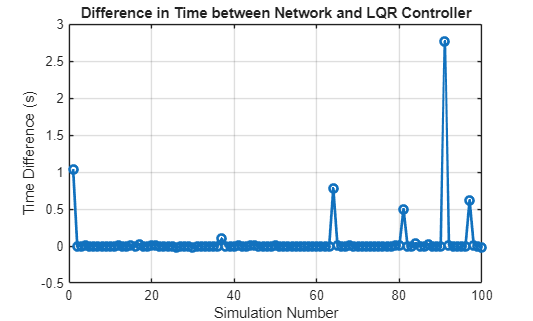


figure;
plot(1:numSims, time_diffs, 'o-', 'LineWidth', 2);
xlabel('Simulation Number');
ylabel('Time Difference (s)');
title('Difference in Time between Network and LQR Controller');
grid on;

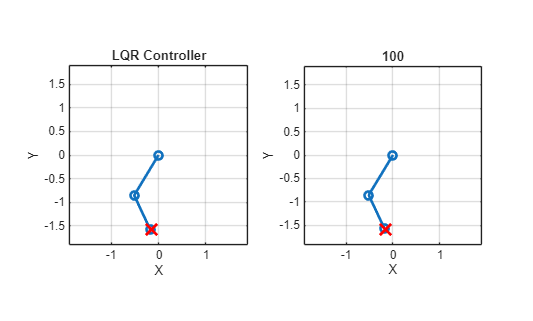


%% Animation
simIdx = 7;
trajLQR = lqrTrajectories{simIdx};
trajNet = netTrajectories{simIdx};
target = targetEE{simIdx};

numStepsLQR = size(trajLQR,2);
numStepsNet = size(trajNet,2);
maxSteps = max(numStepsLQR, numStepsNet);

figure;
subplot(1,2,1);
hLQR_arm = plot(0,0,'-o','LineWidth',2); hold on;
plot(target(1), target(2), 'rx', 'MarkerSize', 12, 'LineWidth', 2);
axis equal; grid on; xlabel('X'); ylabel('Y'); title('LQR Controller');
xlim([-1.9,1.9]); ylim([-1.9,1.9]);

subplot(1,2,2);
hNet_arm = plot(0,0,'-o','LineWidth',2); hold on;
plot(target(1), target(2), 'rx', 'MarkerSize', 12, 'LineWidth', 2);
axis equal; grid on; xlabel('X'); ylabel('Y'); title('Neural Network Controller');
xlim([-1.9,1.9]); ylim([-1.9,1.9]);

for k = 1:maxSteps
    if k <= numStepsLQR, th1 = trajLQR(1,k); th2 = trajLQR(2,k);
    else, th1 = trajLQR(1,end); th2 = trajLQR(2,end); end
    elbow_LQR = [l1*cos(th1); l1*sin(th1)];
    endEffector_LQR = elbow_LQR + [l2*cos(th1+th2); l2*sin(th1+th2)];
    set(hLQR_arm,'XData',[0, elbow_LQR(1), endEffector_LQR(1)],'YData',[0, elbow_LQR(2), endEffector_LQR(2)]);
    title(num2str(100*k/maxSteps))
    
    if k <= numStepsNet, th1n = trajNet(1,k); th2n = trajNet(2,k);
    else, th1n = trajNet(1,end); th2n = trajNet(2,end); end
    elbow_Net = [l1*cos(th1n); l1*sin(th1n)];
    endEffector_Net = elbow_Net + [l2*cos(th1n+th2n); l2*sin(th1n+th2n)];
    set(hNet_arm,'XData',[0, elbow_Net(1), endEffector_Net(1)],'YData',[0, elbow_Net(2), endEffector_Net(2)]);
    drawnow; pause(dt);
end


[~,idx] = maxk(time_diffs,4);
time_diffs2 = time_diffs; time_diffs2(idx) = [];
mean(time_diffs2)

ans = 0.0064


%% Save Test Sequence
testSequence.dt = dt;
testSequence.T  = T;
testSequence.t  = t;
testSequence.l1 = l1;
testSequence.l2 = l2;
testSequence.A  = A;
testSequence.B  = B;
testSequence.K  = K;
testSequence.mu_X     = mu_X;
testSequence.sigma_X  = sigma_X;
testSequence.mu_Y     = mu_Y;
testSequence.sigma_Y  = sigma_Y;
testSequence.numInputs = numInputs;
testSequence.numSims = numSims;
testSequence.sampleInterval = sampleInterval;

%% ---------- Local function (robust concatenation) ----------
function M = localConcat(C, idx)
% Concatenate C{idx(i)} horizontally, skipping empties.
M = [];
for ii = 1:numel(idx)
    ci = C{idx(ii)};
    if ~isempty(ci)
        M = [M, ci]; %#ok<AGROW>
    end
end
end

